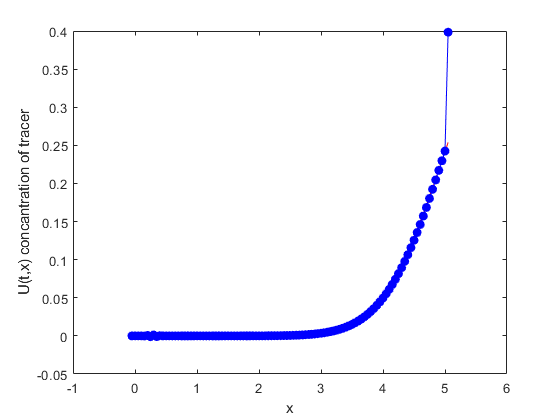

clear
clc
xmin=0; %minimum x
xmax=5; %maximum x
N=100;
dt=0.1;%time step
t=0;   %initial time
tmax=1; %maximum time
v=1;   %velocity
a=0.02; %diffusion constant
%discretise domain
dx=(xmax-xmin)/N;
x=xmin-dx: dx: xmax+dx;

%set initial condition
u0=(1/sqrt(2*pi))*exp(-((x-5).^2)/2);
u=u0;
u1=u0;
unp1=u0;
unp2=u0;

%loop through time
nsteps=tmax/dt;
for n= 1:nsteps 
    %calculate boundary conditions
    for i = 2:N+2
        unp1(i)= u(i)- v*dt/dx*(u(i)-u(i-1));
        
    end
    t=t+dt;
    u=unp1;
    %calculate exact solution
    exact=(1/sqrt(2*pi))*exp(-((x-5-v*t).^2)/2);
    
    %plot solution
    plot(x,exact,'r-');
    hold on
    plot(x,u,'bo-','MarkerFaceColor','b');
    hold off
    xlabel('x');
    ylabel('U(t,x) concantration of tracer');
   
    shg
    pause(dt);
end

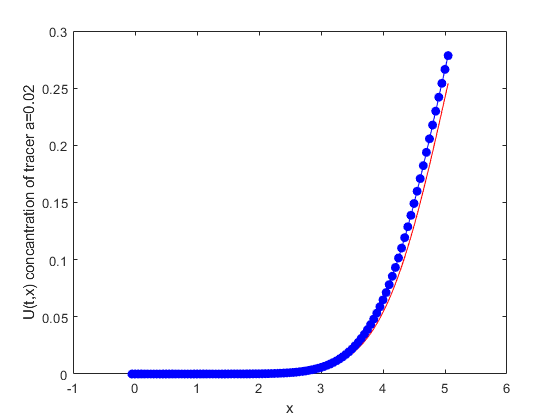


for n= 2:nsteps 
    %calculate boundary conditions
    for i = 3:N+3
        unp2(i)= u1(i)- v*dt/dx*(u1(i)-u1(i-1))+(dt/(dx^2))*(a*(u1(i)-2*u1(i-1)+u1(i-2)));
    end
    t=t+dt;
    u1=unp2;
   
    %plot solution
    plot(x,exact,'r-');
    hold on
    plot(x,u1,'bo-','MarkerFaceColor','b');
    hold off
    xlabel('x');
    ylabel('U(t,x) concantration of tracer a=0.02');
   
    shg
    pause(dt);
end